# Comparing Antenna Array Calculations with NeoRadium

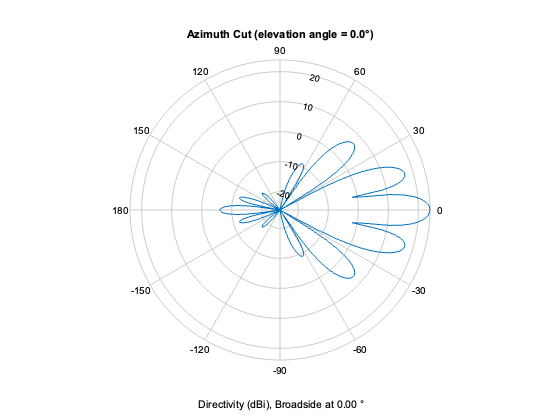

fc = 6e9;
lambda = c/fc;
antenna3 = phased.NRAntennaElement('PolarizationAngle', 0);
antenna4 = phased.NRAntennaElement('PolarizationAngle', 90);

array = phased.NRRectangularPanelArray('ElementSet', ...
        {antenna3, antenna4},'Size',[4, 4, 2, 2],'Spacing', ...
        [0.5*lambda, 0.5*lambda,3*lambda, 3*lambda]);
pattern(array,fc,-180:180,0,'CoordinateSystem','polar','type', 'directivity');

a = pattern(array,fc,-180:180,0,'CoordinateSystem','polar','type', 'directivity');
a(176:185)

ans =   20.064453075620577
  21.543344443325395
  22.606251347704131
  23.326312953200102
  23.744424081280272
  23.881624200315912
  23.744424081280272
  23.326312953200102
  22.606251347704131
  21.543344443325395


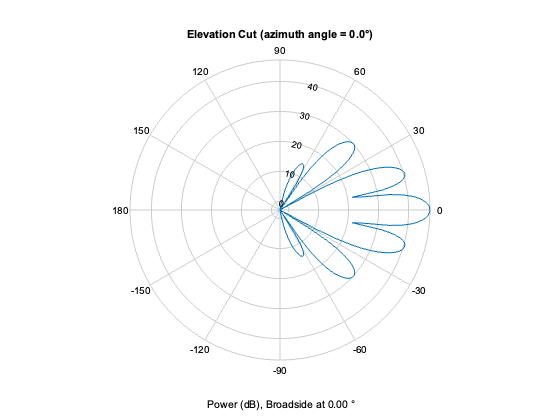

pattern(array,fc,0,-90:90,'CoordinateSystem','polar','type', 'powerdb', 'Normalize', false);

a = pattern(array,fc,0,-90:90,'CoordinateSystem','polar','type', 'powerdb', 'Normalize', false);
a(131:140)

ans =   29.631462073066359
  29.999300797452008
  30.137113869304358
  30.063848223620653
  29.792025091268272
  29.328758777536336
  28.676126926756012
  27.830946524841181
  26.783853085967905
  25.517361971175376


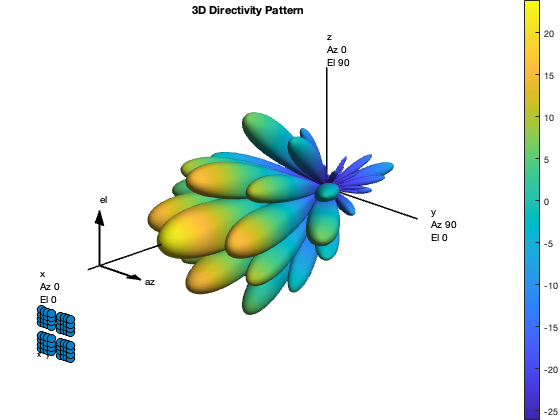


tic;
pattern(array,fc,'ShowArray',true);

toc;

Elapsed time is 122.892562 seconds.


% Saving the files 
outPath = fileparts(matlab.desktop.editor.getActiveFilename);

directivity = pattern(array,fc,'ShowArray',true);
save(strcat(outPath,'/ArrayDirectivity.mat'),'directivity');

powerDb = pattern(array,fc,'ShowArray',true, 'type', 'powerdb', 'Normalize', false);
save(strcat(outPath,'/ArrayPowerDb.mat'),'powerDb');

field = pattern(array,fc,'ShowArray',true, 'type', 'efield', 'Normalize', false);
save(strcat(outPath,'/ArrayField.mat'),'field');

directivity(86:95,181)

ans =   20.064084492184577
  21.542975859889395
  22.605882764268188
  23.325944369764102
  23.744055497844329
  23.881255616879912
  23.744055497844329
  23.325944369764102
  22.605882764268188
  21.542975859889395
